## Test Functionality for HW3 - get_satpos.m

clear;
% add path to products, hw03 folder
addpath('/Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/matlab_utils/');
addpath('/Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/products/');
addpath('/Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/hw03/');


% Choose broadcast orbit file for 10-20-2019
[eph,alpha,beta,dow] = ...
    read_rinexn('/Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/products/brdc2920.19n');

-------------
Reading /Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/products/brdc2920.19n


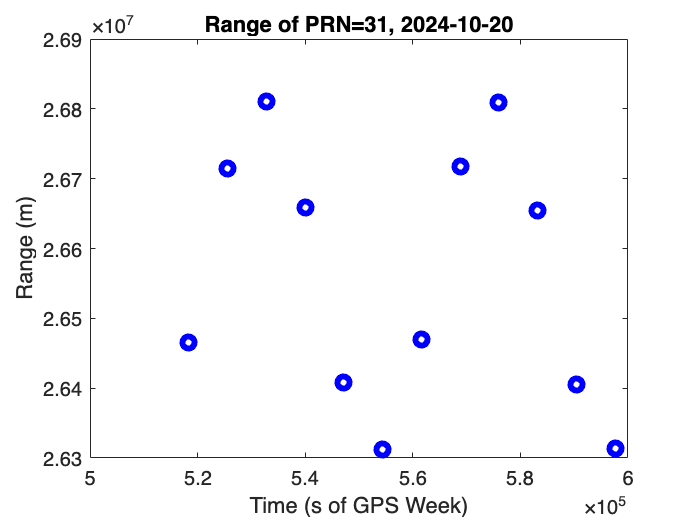


% Choose satellite PRN = 31
sv = 31;

% "then to look at the difference you calculate it at 12 times
% in the eph array you have 12 different times when you have all 
% 23 ephemeris values at 0 2:00 4:00 6:00 etc.
% So then you output xyz coordinate at each of those times. 
% So you would have 12 output positions at 12 different times."
hr = 3600;
t0 = 6*24*3600;
t1 = 6*24*3600 + 2*hr;

t = zeros(1, 12);
for i=0:11
    t(i+1) = t0 + 2*hr*i;
end

% Create pos arrays same length as t
Xarr = zeros(1,length(t));
Yarr = zeros(1,length(t));
Zarr = zeros(1,length(t));

for i=1:length(t)
    [X, Y, Z] = get_satpos(t(i), sv, eph);
    Xarr(i) = X;
    Yarr(i) = Y;
    Zarr(i) = Z;
end

range = sqrt(Xarr.^2 + Yarr.^2 + Zarr.^2);
plot(t,range,"bo",LineWidth=3);
title("Range of PRN=31, 2024-10-20");
xlabel("Time (s of GPS Week)");
ylabel("Range (m)");

Do again for 2024-10-19

% Choose broadcast orbit file for 10-20-2019
[eph2,alpha,beta,dow] = ...
    read_rinexn(['/Users/p3choi/SIOG_GNSS-GPS/' ...
    'SIOG230_GNS_Geodesy/products/brdc2910.19n']);

-------------
Reading /Users/p3choi/SIOG_GNSS-GPS/SIOG230_GNS_Geodesy/products/brdc2910.19n


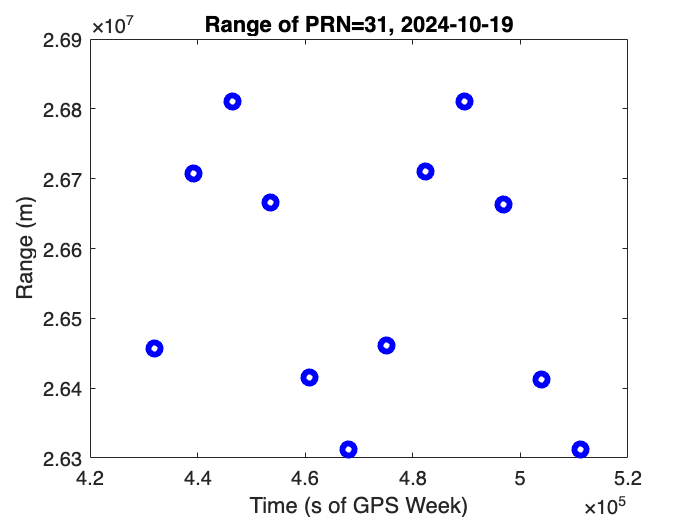


% Choose satellite PRN = 31
sv = 31;

hr = 3600;
% Choose correct starting epoch
t0 = 5*24*3600;

t = zeros(1, 12);
for i=0:11
    t(i+1) = t0 + 2*hr*i;
end

% Create pos arrays same length as t
Xarr2 = zeros(1,length(t));
Yarr2 = zeros(1,length(t));
Zarr2 = zeros(1,length(t));

for i=1:length(t)
    [X2, Y2, Z2] = get_satpos(t(i), sv, eph2);
    Xarr2(i) = X2;
    Yarr2(i) = Y2;
    Zarr2(i) = Z2;
end

range2 = sqrt(Xarr2.^2 + Yarr2.^2 + Zarr2.^2);
plot(t,range2,"bo",LineWidth=3);
title("Range of PRN=31, 2024-10-19");
xlabel("Time (s of GPS Week)");
ylabel("Range (m)");

Testing, in progress: read and compare .sp3 to broadcast orbit results


%%%% Read igs20756.sp3
%#cP2019 10 19
[sp3,sv,excl_sat] = read_sp3(['/Users/p3choi/SIOG_GNSS-GPS/'...
    'SIOG230_GNS_Geodesy/products/igs20756.sp3']);

Ts = sp3.prn31(:,1);
Xs = sp3.prn31(:,2);
Ys = sp3.prn31(:,3);
Zs = sp3.prn31(:,4);
dTs = sp3.prn31(:,5);
% Choose correct starting epoch
% t0 = 5*24*3600;
% 
% t = zeros(1, 12);
% for i=0:11
%     t(i+1) = t0 + 2*hr*i;
% end